% LS_linear
% Examples of Least Square Straight Line
% Material Test

clear all
close all
clc
format compact

xi = [10 15 20 25 40 50 55 60 75];
yi = [5 20 18 40 33 54 70 60 78];

% Plot original data points
hold on
plot(xi,yi,'.','markersize',15)
axis([0,max(xi),0,max(yi)])
xlabel('time')
ylabel('y')

% Fit a straight line y=a1 x + a0 to the "test" data, EQUATION

a1_a0=polyfit(xi,yi,1); % Polynomial of Order 1
strength1 = polyval(a1_a0,32)

strength1 = 34.7049

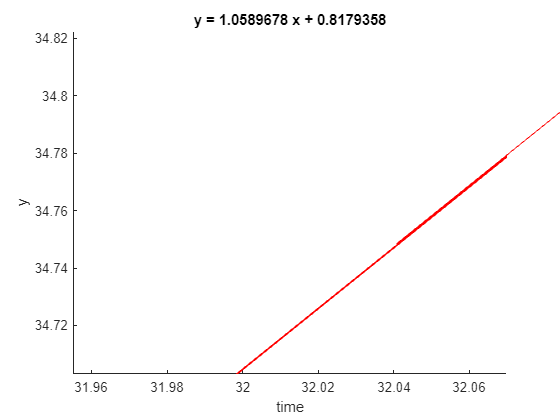

% Plot the polynomials
x = [0 max(xi)];
f1=polyval(a1_a0,x);
plot(x,f1,'-r','linewidth',2)
str=sprintf('y = %f8 x + %f8', a1_a0(1),a1_a0(2));
title(str)
hold off



% Fit a straight line y=a1 x to the "test" data, ZERO INTERCEPT

figure

hold on
plot(xi,yi,'.','markersize',15)
axis([0,max(xi),0,max(yi)])
xlabel('time')
ylabel('y')


sx2 = sum(xi.*xi);
sxy = sum(xi.*yi);
a = sxy/sx2;
strength2 = a*32

strength2 = 34.4045

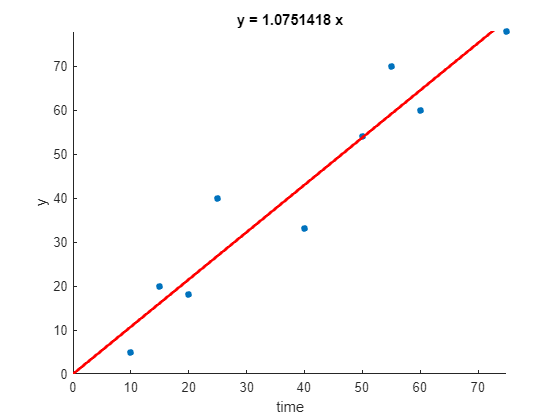


% Plot the polynomials
x = [0 max(xi)];
f2 = a*x;
plot(x,f2,'-r','linewidth',2)
str=sprintf('y = %f8 x', a);
title(str)